图像目录

imgroot = 'source\test3\';

# 利用前60帧建立背景模型

[x,y,z] = size(imread([imgroot,num2str(1),'.jpg']));
frame_all = zeros(x,y,z);

## 取60帧平均值

for i=1:60
    frame_t = imread([imgroot,num2str(i),'.jpg']);
    frame_all = frame_all + double(frame_t);
end
frame_avg = double(frame_all) / 60;

## 帧间差平均值，inter设置为3

inter = 3;
F_t = zeros(x,y,z);
for i=inter+1:60
    temp_t = abs(imread([imgroot,num2str(i),'.jpg'])-imread([imgroot,num2str(i-inter),'.jpg']));
    F_t = F_t + double(temp_t);
end
u_diff = F_t / 60;

## 标准差

F_t_sqrt = zeros(x,y,z);
for i=inter+2:60
    temp_t = abs(imread([imgroot,num2str(i),'.jpg'])-imread([imgroot,num2str(i-inter),'.jpg']));
    temp_t = double(temp_t);
    F_t_sqrt = F_t_sqrt + (temp_t-u_diff).*(temp_t-u_diff);
end
diff_std_sqrt = F_t_sqrt / 60;
diff_std_sqrt = double(diff_std_sqrt);
diff_std = sqrt(diff_std_sqrt);

## 获取阈值，β取2

threshold = u_diff + 2*diff_std;

## 做差得到前景

d = abs(imread([imgroot,num2str(61),'.jpg']) - uint8(frame_all));

## 阈值判断

outframe = d > threshold;

## 查看结果

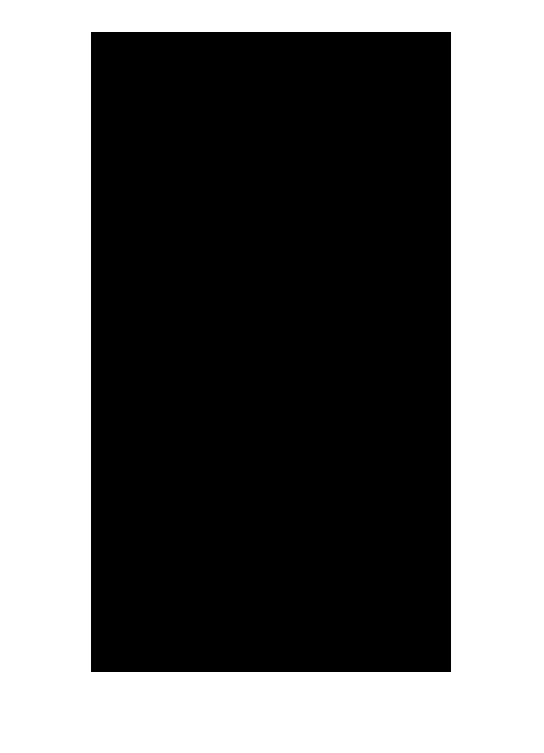

figure;
outframe = uint8(outframe);
outframe = rgb2gray(outframe);
imshow(outframe);